# trf_mkFigure5

Description:

% Dpendencies: calcnoiseceiling.m from knkutil.

## Load files

whichData    = 'fmri1'; 
dataLoc      = fullfile(fileparts(temporalfMRIRootPath), 'files');

[a,b]        = loadfiles(dataLoc, whichData);

% extract and reshape the data
data_origDim = a.(whichData).data;           % dimensions: 4 subjects x 9 rois x 100 bootstraps x 13 temporal conditions
data         = squeeze(mean(data_origDim)); % dimensions: 9 rois x 100 bootstraps x 13 temproal conditions
roiNms       = a.(whichData).nm;
nRois        = length(roiNms);

% extract model parameters
lin = b.(whichData).lin;
stn = b.(whichData).stn; % the CTS model - variation: static temproal normalization

## Compute for Figure 5A

for k = 1 : nRois
    % mean and std of data
    mdata(k, :) = squeeze(mean(data(k, :, :), 2));
    sdata(k, :) = squeeze(std(data(k, :, :), [], 2));
    
    % mean and std of linear prediction
    idx = (k - 1) * 100 + 1 : k * 100;
    mlinxprd(k, :) = median(lin.xPrd(:, idx), 2);
    slinxprd(k, :, 1) = mlinxprd(k, :)' - prctile(lin.xPrd(:, idx), 25, 2);
    slinxprd(k, :, 2) = prctile(lin.xPrd(:, idx), 75, 2) - mlinxprd(k, :)';
    
    % mean and std of cts prediction
    idx = (k - 1) * 100 + 1 : k * 100;
    mstnxprd(k, :) = median(stn.xPrd(:, idx), 2);
    sstnxprd(k, :, 1) = mstnxprd(k, :)' - prctile(stn.xPrd(:, idx), 25, 2);
    sstnxprd(k, :, 2) = prctile(stn.xPrd(:, idx), 75, 2) - mstnxprd(k, :)';
    
    % median and CI of linear and cts xr2
    slinxr2(k, :) = prctile(lin.xr2(idx), [25, 75]);
    sstnxr2(k, :) = prctile(stn.xr2(idx), [25, 75]);
    
    mlinxr2(k) = median(lin.xr2(idx));
    mstnxr2(k) = median(stn.xr2(idx)); 
end

## Compute for Figure 5B

% compute noise ceiling
f  = b.fmri1.noiseCeiling.f;
dist = b.fmri1.noiseCeiling.dist;

% compute x-validated flat model prediction
for ii = 1:size(data, 3)
    predFlat(:,:,ii) = mean(data(:,:,setdiff(1:13,ii)),3);
end
R2flat   = 1 - sum((predFlat-data).^2, 3) ./ sum(data.^2,3);
mflatxr2 = median(R2flat, 2).*100;


## Plot Figure 5

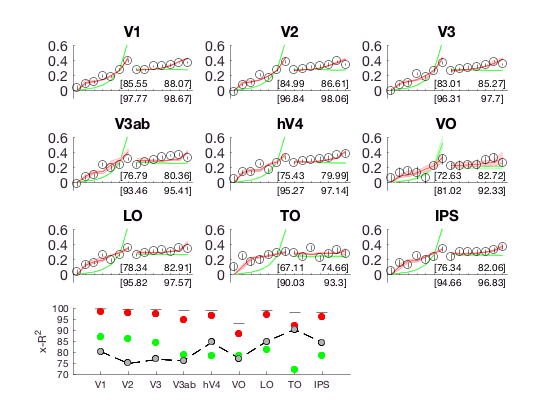

figure (5), clf

% plot data and model fit
order = [13, 1 : 6, 5, 7 : 12];

for k = 1 : nRois
   subplot(4, 3, k)
   % plot linear predictions
   shadedErrorBar(1 : 7, mlinxprd(k, order(1 : 7)), squeeze(slinxprd(k, order(1 : 7), :)), 'g-'), hold on
   shadedErrorBar(8 : 14, mlinxprd(k, order(8 : 14)), squeeze(slinxprd(k, order(8 : 14), :)), 'g-')
   
   % plot CTS predictions
   shadedErrorBar(1 : 7, mstnxprd(k, order(1 : 7)), squeeze(sstnxprd(k, order(1 : 7), :)), 'r-')
   shadedErrorBar(8 : 14, mstnxprd(k, order(8 : 14)), squeeze(sstnxprd(k, order(8 : 14), :)), 'r-')
   
   % plot data
   plot(mdata(k, order), 'ko', 'markersize', 8), 
   for k1 = 1 : length(order)
       plot([k1, k1], [mdata(k, order(k1))-sdata(k, order(k1)), mdata(k, order(k1))+sdata(k, order(k1))], 'k-')
   end
   
   % text : xR2
   text(6, 0.1, sprintf('[%s]', num2str(slinxr2(k, :), 4)))
   text(6, -0.1, sprintf('[%s]', num2str(sstnxr2(k, :), 4)))
   
   box off,xlim([0.5, length(order) + 0.5]), set(gca, 'xtick', [1 : length(order)], 'xticklabel', '', 'xaxislocation', 'origin', 'fontsize', 14), 
   set(gca, 'ytick', [0, 0.2, 0.4, 0.6]), ylim([-0.1, 0.6]), title(roiNms{k})
end

subplot(4, 3, 10 : 11)
for k = 1 : 9
   plot([k - 0.2, k + 0.2], [f(k), f(k)], 'k-'), hold on,
   plot(mlinxr2, 'go', 'markerfacecolor', 'g')
   plot(mstnxr2, 'ro', 'markerfacecolor', 'r')
   plot(mflatxr2, 'ko--', 'markerfacecolor', 0.7 * ones(1, 3))
   box off, ylim([70, 100]), set(gca, 'xtick', 1 : nRois, 'xticklabel', roiNms, 'ytick', 70 : 5 : 100), ylabel('x-R^2')
end